# (1) ホテリングの$T^2$法による異常検知

## はじめに

教師無し学習による異常検知の手法のうち、ホテリングの$T^2$法はさまざまな分野で長年使われてきた、最も典型的な手法の一つです。この手法は、単峰性のデータ分布 (多次元空間内の1点を中心とした分布) を想定しています。この想定のもと、多次元空間内でのマハラノビス距離を指標に各データ点の異常度を決めます。

## 前処理済みのデータの読み込み

あらかじめ作成した前処理済みのデータを読み込みます。

load('Preprocessed_FD001.mat');

## ホテリングの$T^2$法

簡単のため、以下では第1主成分-第2主成分平面上でのデータ分布に対して、ホテリングの$T^2$法を適用します。

まず、'long' とラベル付けされたデータをもとに単位空間 (Unit space) を作成します。このとき、説明変数の数 (= 2) はデータ点数 (= 20,631) と比べて大幅に少ないため、マハラノビス距離分布は「自由度2のカイ二乗分布」として扱うことができます。

次に、異常を判別するための閾値として、発生頻度が 5%, 1% および 0.1% を想定し、上記で求めたカイ二乗分布から、これら発生頻度それぞれに対する閾値を求めます。

最後に、主成分平面上でのデータ点の分布と、発生頻度 5%, 1% および 0.1% の異常を判別するための境界線を図示します。

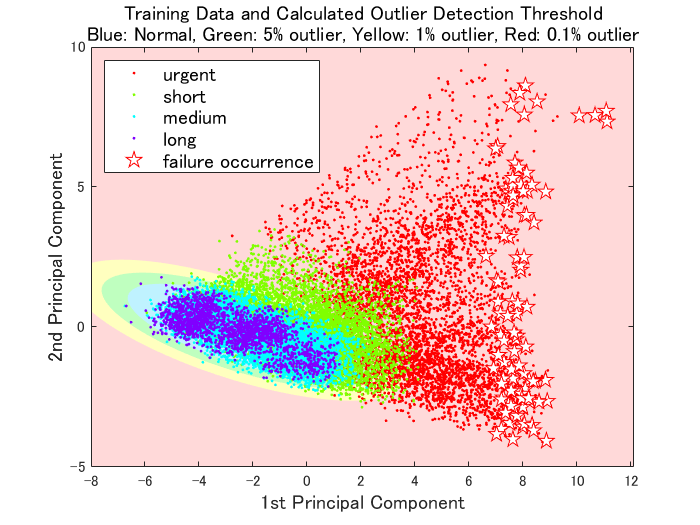

% 発生頻度が 5%, 1% および 0.1% の異常を検出するための閾値を求めるための準備
idx = (dataTrainZ.Label == 'long');
th = [0.001, 0.01, 0.05];
C = cell(3,1);

% 各データ点のマハラノビス距離を算出
d = 0.1;
[x1Grid, x2Grid] = meshgrid(-8:d:8, -8:d:8);
aGrid = mahal([x1Grid(:) x2Grid(:)], score(idx,1:2));
aGrid = reshape(aGrid, size(x1Grid,1), size(x2Grid,2));

% カイ二乗分布をもとに、発生頻度 5%, 1% および 0.1% の異常検出のための閾値を算出
for kk=1:3
    lev = chi2inv((1-th(kk)),2);
    C{kk} = contourc((-8:d:8), (-8:d:8), aGrid, [lev lev]);
end

% 発生頻度 5%, 1% および 0.1% に対応する色を設定
col5per = [0.75 0.95 1];
col1per = [0.75 1 0.75];
col01per = [1 1 0.75];
colAnomaly = [1 0.85 0.85];

% 結果を可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTrainZ.Label);
idx = dataTrainZ.Time == 0;
s2 = plot(score(idx,1),...
    score(idx,2),'rp','MarkerSize',10,'MarkerFaceColor','w');
legend([s1; s2],{'urgent','short','medium','long','failure occurrence'},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
ax.Layer = 'top';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Training Data and Calculated Outlier Detection Threshold';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

## 検証用データによる確認

ここまでの検討では、学習用データから閾値を決め、学習用データで確認していました。しかしながら、より現実に即した性能を評価するには、閾値を決める際に用いたデータとは別のデータに対して異常判別の可否を確認する必要があります。そこで以下では、学習用データをもとに算出した閾値を、検証用データに対して適用してみます。

その結果、検証用データで 'urgent' とラベル付けされたデータを検出するには、1% 用の閾値を用いると良いということが確認できました。

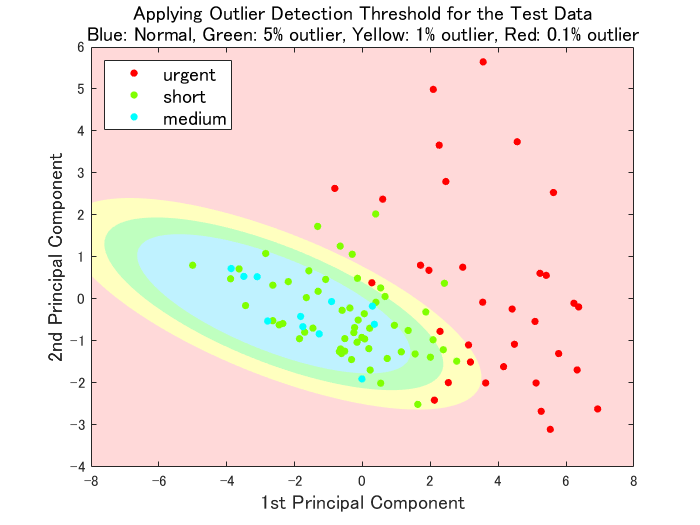

% 検証用データを標準化
dataTestZ = dataTest;
dataTestZ{:,3:end-1} = (dataTest{:,3:end-1} - mu)./sigma;

% 検証用データの主成分を算出
score = dataTestZ{:,3:end-1}*wcoeff;

% 結果を可視化
figure
plotContourmatrix(C{1}, col01per);
plotContourmatrix(C{2}, col1per);
plotContourmatrix(C{3}, col5per);
hold on;
s1 = gscatter(score(:,1),...
    score(:,2),...
    dataTestZ.Label);
legend(s1,{s1.DisplayName},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
ax = gca;
ax.Color = colAnomaly;
ax.Box = 'on';
ax.Layer = 'top';
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
title({'Applying Outlier Detection Threshold for the Test Data';...
    'Blue: Normal, Green: 5% outlier, Yellow: 1% outlier, Red: 0.1% outlier'},'FontSize',12)

*Copyright 2020 The MathWorks, Inc.*